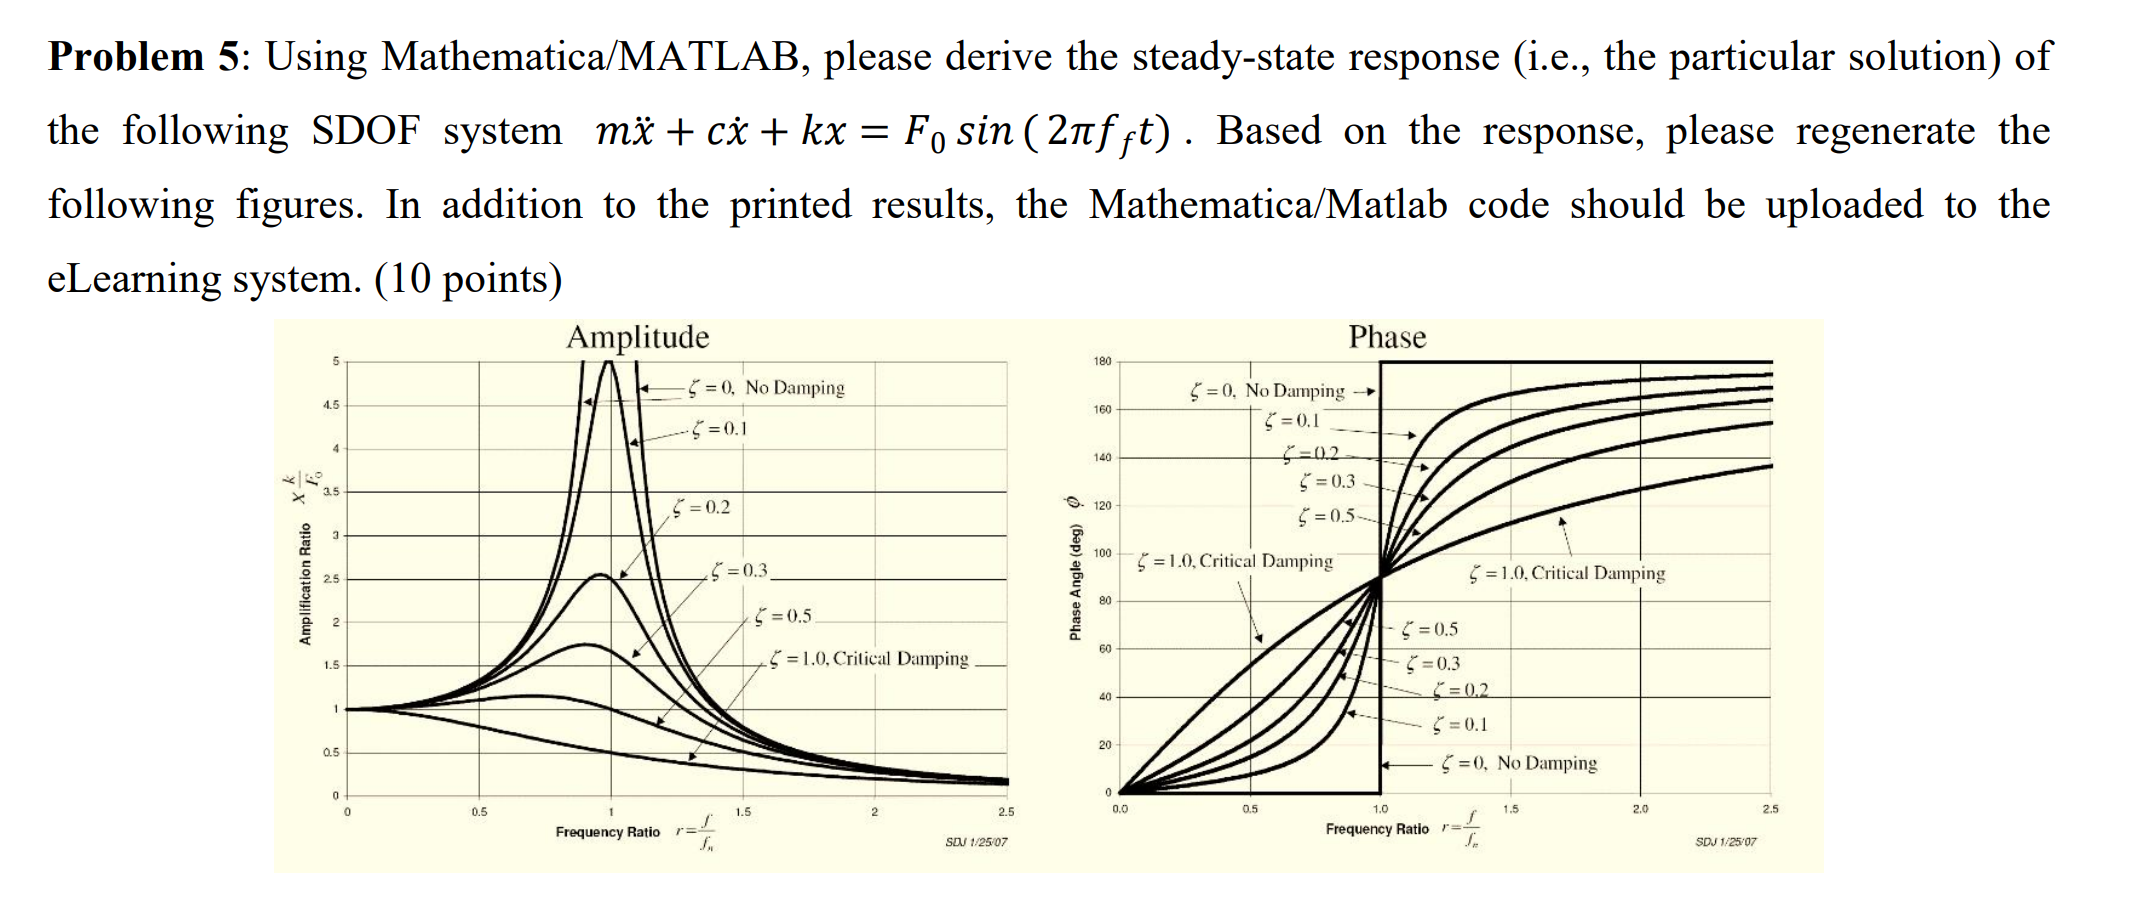

clear; clc;
syms t x(t) c k F_0 omega_f m
f = @(v) m * diff(v, 2) + c * diff(v, 1) + k * v;
eq = f(x) == F_0 * sin(omega_f*t)

$$eq(t) = m\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+c\,\frac{\partial }{\partial t}x\left(t\right)+k\,x\left(t\right)=F_{0}\,\sin\left(\omega_{f}\,t\right)$$

assume(m > 0); % 添加条件 m > 0
assume(k > 0); % 添加条件 k > 0
res = dsolve(eq)

$$res = \begin{array}{l} C_{2}\,\sigma_{3}+C_{1}\,\sigma_{2}+\frac{F_{0}\,\sigma_{3}\,{\mathrm{e}}^{\frac{c\,t+t\,\sigma_{4}}{2\,m}}\,\left(\sigma_{1}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c+\sigma_{4}\right)}{2\,m}\right)}{\left(\frac{{\left(c+\sigma_{4}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{4}}-\frac{F_{0}\,{\mathrm{e}}^{\frac{c\,t-t\,\sigma_{4}}{2\,m}}\,\sigma_{2}\,\left(\sigma_{1}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c-\sigma_{4}\right)}{2\,m}\right)}{\left(\frac{{\left(c-\sigma_{4}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{4}}\\ \mathrm{where}\\ \sigma_{1}=\omega_{f}\,\cos\left(\omega_{f}\,t\right)\\ \sigma_{2}={\mathrm{e}}^{-\frac{t\,\left(c-\sigma_{4}\right)}{2\,m}}\\ \sigma_{3}={\mathrm{e}}^{-\frac{t\,\left(c+\sigma_{4}\right)}{2\,m}}\\ \sigma_{4}=\sqrt{c^{2}-4\,k\,m} \end{array}$$

simplify(res)

$$ans = \begin{array}{l} C_{1}\,{\mathrm{e}}^{-\frac{c\,t-t\,\sigma_{1}}{2\,m}}+C_{2}\,{\mathrm{e}}^{-\frac{c\,t+t\,\sigma_{1}}{2\,m}}+\frac{F_{0}\,\left(\sigma_{2}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c+\sigma_{1}\right)}{2\,m}\right)}{\left(\frac{{\left(c+\sigma_{1}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{1}}-\frac{F_{0}\,\left(\sigma_{2}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c-\sigma_{1}\right)}{2\,m}\right)}{\left(\frac{{\left(c-\sigma_{1}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{c^{2}-4\,k\,m}\\ \sigma_{2}=\omega_{f}\,\cos\left(\omega_{f}\,t\right) \end{array}$$

syms C1 C2
x_p = subs(res, [C1 C2], [0 0])

$$x\_p = \begin{array}{l} \frac{F_{0}\,{\mathrm{e}}^{-\frac{t\,\left(c+\sigma_{1}\right)}{2\,m}}\,{\mathrm{e}}^{\frac{c\,t+t\,\sigma_{1}}{2\,m}}\,\left(\sigma_{2}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c+\sigma_{1}\right)}{2\,m}\right)}{\left(\frac{{\left(c+\sigma_{1}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{1}}-\frac{F_{0}\,{\mathrm{e}}^{\frac{c\,t-t\,\sigma_{1}}{2\,m}}\,{\mathrm{e}}^{-\frac{t\,\left(c-\sigma_{1}\right)}{2\,m}}\,\left(\sigma_{2}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c-\sigma_{1}\right)}{2\,m}\right)}{\left(\frac{{\left(c-\sigma_{1}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{c^{2}-4\,k\,m}\\ \sigma_{2}=\omega_{f}\,\cos\left(\omega_{f}\,t\right) \end{array}$$

x_h= res - x_p

$$x\_h = C_{2}\,{\mathrm{e}}^{-\frac{t\,\left(c+\sqrt{c^{2}-4\,k\,m}\right)}{2\,m}}+C_{1}\,{\mathrm{e}}^{-\frac{t\,\left(c-\sqrt{c^{2}-4\,k\,m}\right)}{2\,m}}$$

check_res = f(res)

check_x_h = f(x_h)

$$check\_x\_h = \begin{array}{l} m\,\left(\frac{C_{1}\,\sigma_{1}\,{\sigma_{3}}^{2}}{4\,m^{2}}+\frac{C_{2}\,\sigma_{2}\,{\sigma_{4}}^{2}}{4\,m^{2}}\right)-c\,\left(\frac{C_{1}\,\sigma_{1}\,\sigma_{3}}{2\,m}+\frac{C_{2}\,\sigma_{2}\,\sigma_{4}}{2\,m}\right)+k\,\left(C_{2}\,\sigma_{2}+C_{1}\,\sigma_{1}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{t\,\sigma_{3}}{2\,m}}\\ \sigma_{2}={\mathrm{e}}^{-\frac{t\,\sigma_{4}}{2\,m}}\\ \sigma_{3}=c-\sqrt{c^{2}-4\,k\,m}\\ \sigma_{4}=c+\sqrt{c^{2}-4\,k\,m} \end{array}$$

check_x_p = f(x_p)

$$check\_x\_p = \begin{array}{l} k\,\left(\frac{F_{0}\,\sigma_{9}\,\sigma_{7}\,\left(\sigma_{3}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c+\sigma_{10}\right)}{2\,m}\right)}{\sigma_{5}}-\frac{F_{0}\,\sigma_{6}\,\sigma_{8}\,\left(\sigma_{3}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c-\sigma_{10}\right)}{2\,m}\right)}{\sigma_{4}}\right)-c\,\left(\frac{F_{0}\,\sigma_{9}\,\sigma_{7}\,\left(\sigma_{1}+\frac{\omega_{f}\,\cos\left(\omega_{f}\,t\right)\,\left(c+\sigma_{10}\right)}{2\,m}\right)}{\sigma_{5}}-\frac{F_{0}\,\sigma_{6}\,\sigma_{8}\,\left(\sigma_{1}+\frac{\omega_{f}\,\cos\left(\omega_{f}\,t\right)\,\left(c-\sigma_{10}\right)}{2\,m}\right)}{\sigma_{4}}\right)-m\,\left(\frac{F_{0}\,\sigma_{9}\,\sigma_{7}\,\left(\sigma_{2}-\frac{{\omega_{f}}^{2}\,\sin\left(\omega_{f}\,t\right)\,\left(c+\sigma_{10}\right)}{2\,m}\right)}{\sigma_{5}}-\frac{F_{0}\,\sigma_{6}\,\sigma_{8}\,\left(\sigma_{2}-\frac{{\omega_{f}}^{2}\,\sin\left(\omega_{f}\,t\right)\,\left(c-\sigma_{10}\right)}{2\,m}\right)}{\sigma_{4}}\right)\\ \mathrm{where}\\ \sigma_{1}={\omega_{f}}^{2}\,\sin\left(\omega_{f}\,t\right)\\ \sigma_{2}={\omega_{f}}^{3}\,\cos\left(\omega_{f}\,t\right)\\ \sigma_{3}=\omega_{f}\,\cos\left(\omega_{f}\,t\right)\\ \sigma_{4}=\left(\frac{{\left(c-\sigma_{10}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{10}\\ \sigma_{5}=\left(\frac{{\left(c+\sigma_{10}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{10}\\ \sigma_{6}={\mathrm{e}}^{\frac{c\,t-t\,\sigma_{10}}{2\,m}}\\ \sigma_{7}={\mathrm{e}}^{\frac{c\,t+t\,\sigma_{10}}{2\,m}}\\ \sigma_{8}={\mathrm{e}}^{-\frac{t\,\left(c-\sigma_{10}\right)}{2\,m}}\\ \sigma_{9}={\mathrm{e}}^{-\frac{t\,\left(c+\sigma_{10}\right)}{2\,m}}\\ \sigma_{10}=\sqrt{c^{2}-4\,k\,m} \end{array}$$

A = abs(x_p)

$$A = \begin{array}{l} \left|\frac{F_{0}\,{\mathrm{e}}^{-\frac{t\,\left(c+\sigma_{1}\right)}{2\,m}}\,{\mathrm{e}}^{\frac{c\,t+t\,\sigma_{1}}{2\,m}}\,\left(\sigma_{2}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c+\sigma_{1}\right)}{2\,m}\right)}{\left(\frac{{\left(c+\sigma_{1}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{1}}-\frac{F_{0}\,{\mathrm{e}}^{\frac{c\,t-t\,\sigma_{1}}{2\,m}}\,{\mathrm{e}}^{-\frac{t\,\left(c-\sigma_{1}\right)}{2\,m}}\,\left(\sigma_{2}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c-\sigma_{1}\right)}{2\,m}\right)}{\left(\frac{{\left(c-\sigma_{1}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{1}}\right|\\ \mathrm{where}\\ \sigma_{1}=\sqrt{c^{2}-4\,k\,m}\\ \sigma_{2}=\omega_{f}\,\cos\left(\omega_{f}\,t\right) \end{array}$$

phi = angle(x_p)

$$phi = \begin{array}{l} \text{angle}\left(\frac{F_{0}\,{\mathrm{e}}^{-\frac{t\,\left(c+\sigma_{1}\right)}{2\,m}}\,{\mathrm{e}}^{\frac{c\,t+t\,\sigma_{1}}{2\,m}}\,\left(\sigma_{2}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c+\sigma_{1}\right)}{2\,m}\right)}{\left(\frac{{\left(c+\sigma_{1}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{1}}-\frac{F_{0}\,{\mathrm{e}}^{\frac{c\,t-t\,\sigma_{1}}{2\,m}}\,{\mathrm{e}}^{-\frac{t\,\left(c-\sigma_{1}\right)}{2\,m}}\,\left(\sigma_{2}-\frac{\sin\left(\omega_{f}\,t\right)\,\left(c-\sigma_{1}\right)}{2\,m}\right)}{\left(\frac{{\left(c-\sigma_{1}\right)}^{2}}{4\,m^{2}}+{\omega_{f}}^{2}\right)\,\sigma_{1}}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{c^{2}-4\,k\,m}\\ \sigma_{2}=\omega_{f}\,\cos\left(\omega_{f}\,t\right) \end{array}$$

clear; clc;
syms t x(t) xi omega_n m omega_f F_0
f = @(v) diff(v, 2) + 2*xi*omega_n*diff(v, 1) + omega_n^2 * v;
f(x)

$$ans(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+2\,\xi \,\omega_{n}\,\frac{\partial }{\partial t}x\left(t\right)+x\left(t\right)\,{\omega_{n}}^{2}$$

eq = f(x) == F_0/m * sin(omega_f*t)

$$eq(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+2\,\xi \,\omega_{n}\,\frac{\partial }{\partial t}x\left(t\right)+x\left(t\right)\,{\omega_{n}}^{2}=\frac{F_{0}\,\sin\left(\omega_{f}\,t\right)}{m}$$

res = simplify(dsolve(eq))

$$res = \begin{array}{l} C_{1}\,{\mathrm{e}}^{\omega_{n}\,t\,\sigma_{4}-\omega_{n}\,t\,\xi }+C_{2}\,{\mathrm{e}}^{-\omega_{n}\,t\,\xi -\omega_{n}\,t\,\sigma_{4}}-\frac{F_{0}\,\left(\sin\left(\omega_{f}\,t\right)\,\sigma_{3}-\sigma_{1}\right)}{2\,m\,\omega_{n}\,\sigma_{4}\,\left({\sigma_{3}}^{2}+{\omega_{f}}^{2}\right)}+\frac{F_{0}\,\left(\sin\left(\omega_{f}\,t\right)\,\sigma_{2}-\sigma_{1}\right)}{2\,m\,\omega_{n}\,\sigma_{4}\,\left({\sigma_{2}}^{2}+{\omega_{f}}^{2}\right)}\\ \mathrm{where}\\ \sigma_{1}=\omega_{f}\,\cos\left(\omega_{f}\,t\right)\\ \sigma_{2}=\omega_{n}\,\xi -\omega_{n}\,\sigma_{4}\\ \sigma_{3}=\omega_{n}\,\xi +\omega_{n}\,\sigma_{4}\\ \sigma_{4}=\sqrt{\xi^{2}-1} \end{array}$$

check_res = f(res)

syms C1 C2
x_p = simplify(subs(res, [C1, C2], [0, 0]))

$$x\_p = -\frac{F_{0}\,\left({\omega_{f}}^{2}\,\sin\left(\omega_{f}\,t\right)-{\omega_{n}}^{2}\,\sin\left(\omega_{f}\,t\right)+2\,\omega_{f}\,\omega_{n}\,\xi \,\cos\left(\omega_{f}\,t\right)\right)}{m\,\left({\omega_{f}}^{4}+4\,{\omega_{f}}^{2}\,{\omega_{n}}^{2}\,\xi^{2}-2\,{\omega_{f}}^{2}\,{\omega_{n}}^{2}+{\omega_{n}}^{4}\right)}$$

check_x_p = simplify(f(x_p))

$$check\_x\_p = \begin{array}{l} \frac{8\,F_{0}\,{\omega_{f}}^{2}\,{\omega_{n}}^{2}\,\sigma_{1}}{m\,{\sigma_{2}}^{2}}-\frac{F_{0}\,{\omega_{n}}^{2}\,\sigma_{1}}{m\,\sigma_{2}}-\frac{4\,F_{0}\,\omega_{f}\,{\omega_{n}}^{2}\,\xi \,\left({\omega_{f}}^{4}\,\cos\left(\omega_{f}\,t\right)+{\omega_{n}}^{4}\,\cos\left(\omega_{f}\,t\right)-2\,{\omega_{f}}^{2}\,{\omega_{n}}^{2}\,\cos\left(\omega_{f}\,t\right)-4\,{\omega_{f}}^{2}\,{\omega_{n}}^{2}\,\xi^{2}\,\cos\left(\omega_{f}\,t\right)+4\,\omega_{f}\,{\omega_{n}}^{3}\,\xi \,\sin\left(\omega_{f}\,t\right)-4\,{\omega_{f}}^{3}\,\omega_{n}\,\xi \,\sin\left(\omega_{f}\,t\right)\right)}{m\,{\sigma_{2}}^{2}}+\frac{32\,F_{0}\,{\omega_{f}}^{3}\,{\omega_{n}}^{3}\,\xi \,\cos\left(\omega_{f}\,t\right)}{m\,{\sigma_{2}}^{2}}-\frac{128\,F_{0}\,{\omega_{f}}^{4}\,{\omega_{n}}^{4}\,\xi^{2}\,\sigma_{1}}{m\,{\sigma_{2}}^{3}}\\ \mathrm{where}\\ \sigma_{1}={\omega_{f}}^{2}\,\sin\left(\omega_{f}\,t\right)-{\omega_{n}}^{2}\,\sin\left(\omega_{f}\,t\right)+2\,\omega_{f}\,\omega_{n}\,\xi \,\cos\left(\omega_{f}\,t\right)\\ \sigma_{2}={\omega_{f}}^{4}+4\,{\omega_{f}}^{2}\,{\omega_{n}}^{2}\,\xi^{2}-2\,{\omega_{f}}^{2}\,{\omega_{n}}^{2}+{\omega_{n}}^{4} \end{array}$$

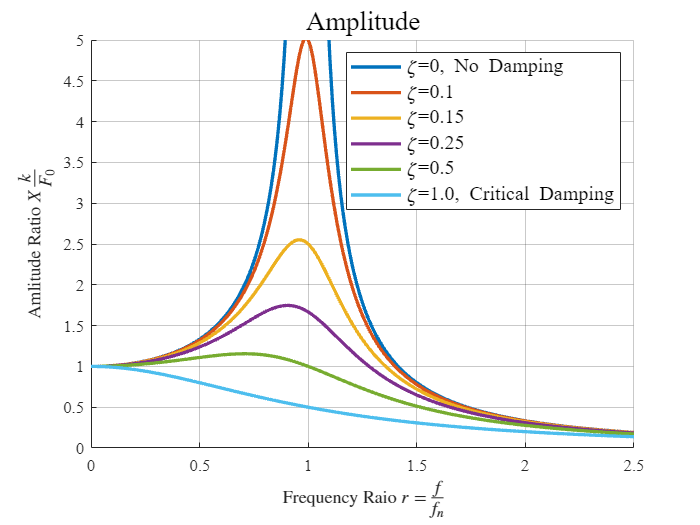

clear; clc;

zetaList = [0 0.1 0.2 0.3 0.5 1]; % different damping ratio

% amplitude generation
figure, hold on
for zeta = zetaList % for every damping ratio
    omegaRatio = 0:0.01:5; % wf/wn
    amplitude = 1 ./ sqrt((1-omegaRatio.^2).^2 + (2*zeta*omegaRatio).^2); % response amplitude
    plot(omegaRatio, amplitude, 'lineWidth',2);
end
hold off
h_a = gca;
set(h_a, 'XLim',[0,2.5], 'YLim',[0,5]); % axis
set(h_a, 'XGrid','on', 'YGrid','on', 'GridLineStyle','-', 'GridColor',[0.15,0.15,0.15], 'GridAlpha',0.25); % grid
xlabel('Frequency Raio $r=\frac{f}{f_n}$', 'Interpreter','Latex'), ylabel('Amlitude Ratio $X\frac{k}{F_0}$', 'Interpreter','Latex'); % label
set(h_a, 'FontName','Times New Roman', 'FontSize',10) % font
title('Amplitude', 'FontSize',16); % title
h_l = legend('\zeta=0, No Damping', '\zeta=0.1', '\zeta=0.15', '\zeta=0.25', '\zeta=0.5', '\zeta=1.0, Critical Damping'); % legend
set(h_l, 'FontSize',12);

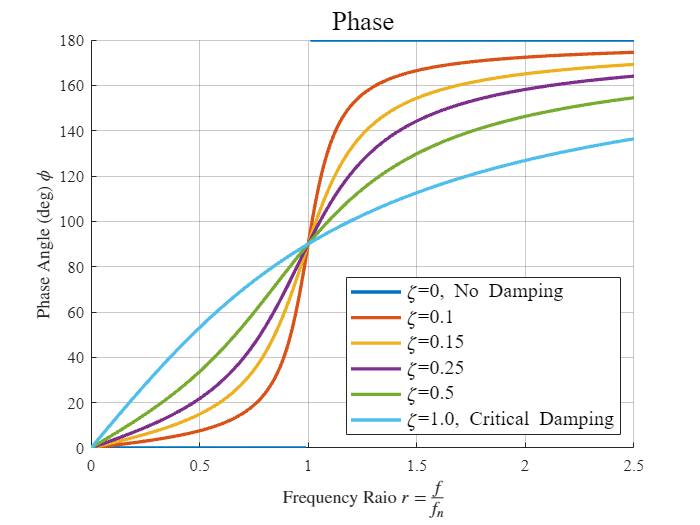


% phase
zetaList = [0 0.1 0.2 0.3 0.5 1]; % different damping ratio
figure, hold on
for zeta = zetaList % for every damping ratio
    omegaRatio = 0:0.01:2.5; % wf/wn
    phase = atan(2*zeta*omegaRatio./(1-omegaRatio.^2));
    phase = phase + pi * (omegaRatio>1);
    plot(omegaRatio, rad2deg(phase), 'lineWidth',2);
end
h_a = gca;
set(h_a, 'XLim',[0, 2.5], 'YLim',[0,180]); % axis
set(h_a, 'XGrid','on', 'YGrid','on', 'GridLineStyle','-', 'GridColor',[0.15,0.15,0.15], 'GridAlpha',0.25); % grid
xlabel('Frequency Raio $r=\frac{f}{f_n}$', 'Interpreter','Latex'), ylabel('Phase Angle (deg) $\phi$', 'Interpreter','Latex'); % label
set(h_a, 'FontName','Times New Roman', 'FontSize',10) % font
title('Phase', 'FontSize',16); % title
h_l = legend('\zeta=0, No Damping', '\zeta=0.1', '\zeta=0.15', '\zeta=0.25', '\zeta=0.5', '\zeta=1.0, Critical Damping', 'Location', 'southeast'); % legend
set(h_l, 'FontSize',12);